# Demo:  Simulating AWGN Noise

In this demo, we review how to simulate discrete-time noise.  In going through this  

- Compute signal and noise levels based on absolute power values

- Add complex Gaussian noise to symbols

- Visualize noise on QAM symbols

- Perform simulations based on SNR without absolute power levels

## Example Transmit Symbols

We will illustrate the noise with a set of 16-QAM symbols

modRate = 4;    % num bits per symbol (4=16 QAM)
M = 2^modRate;  % QAM order
nsym = 1024;    % num symbols

% Generate data
nbits = nsym*modRate;
bits = randi([0,1],nbits,1);
sym = qammod(bits,M,'InputType','bit','UnitAveragePower',true);

## Simulating AWGN Given Absolute Power Levels

Suppose we want to simulate a receiver with the following parameters

Prx = -80;  % RX power in dBm
NF = 6;     % Noise figure in dB
fsamp = 20e6;   % Sample rate in Hz

We can simulate this by computing the absolute energy per sample for the noise and signal and scaling both correctly.

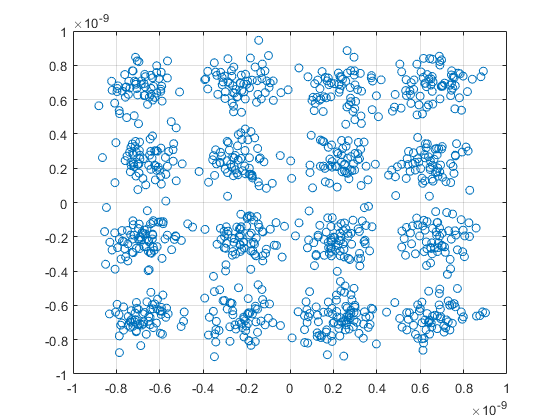

% Noise energy per sample
T = 290;
k=physconst('Boltzmann');
EkT = 10*log10(k*T);
Enoise = EkT + NF;

% Energy per sample in dBJ.
% Note we have to subtract 30 since MATLAB uses W not mW
Es = Prx - 30 - 10*log10(fsamp);

% Rescale signal 
s = 10.^(0.05*Es)*sym / sqrt(mean(abs(sym).^2));

% Generate noise
w = sqrt(10.^(0.1*Enoise)/2)*(randn(nsym,1) +1i*randn(nsym,1));

% Add the noise
r = s + w;

% Plot the constellation
plot(real(r), imag(r), 'o');
grid();

## Using MATLAB's built in Thermal Noise Block

We can also do the simulation with MATLAB's built-in thermal noise block.

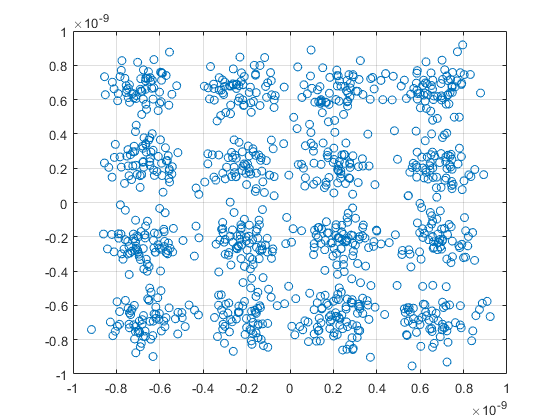


% Energy per sample in dBJ.
% Note we have to subtract 30 since MATLAB uses W not mW
Es = Prx - 30 - 10*log10(fsamp);

% Rescale signal 
s = 10.^(0.05*Es)*sym / sqrt(mean(abs(sym).^2));

% Create a thermal noise object
tn = comm.ThermalNoise('NoiseMethod', 'Noise figure', ...
    'NoiseFigure', NF, 'Add290KAntennaNoise', true);

% Add the noise
r = tn.step(s);


% Plot the constellation
plot(real(r), imag(r), 'o');
grid();

## Simulating Using Relative Signal Levels

We can also run the simulation with arbitrary levels as long as the SNR is maintained.  For this purpose, we first compute the SNR per symbol

EsN0 = Es - Enoise;
fprintf(1, 'Es/N0 = %7.2f dB', EsN0);

Es/N0 =   14.82 dB

We can then set the signal to unit variance and scale the noise to Es/N0 below that.

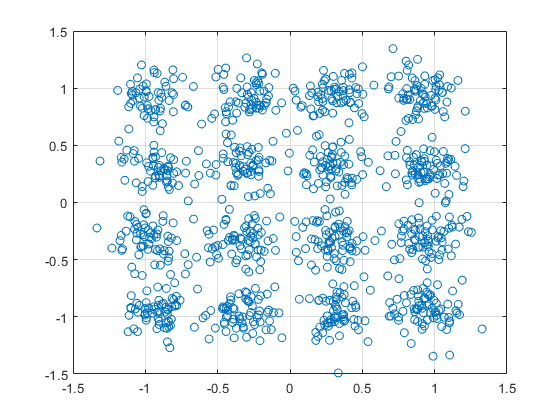

% Rescale signal to unit norm
s = sym / sqrt(mean(abs(sym).^2));

% Generate noise
w = sqrt(10^(-0.1*EsN0)/2)*(randn(nsym,1) +1i*randn(nsym,1));

% Generate signal
r = s + w;
plot(real(r), imag(r), 'o');
grid();